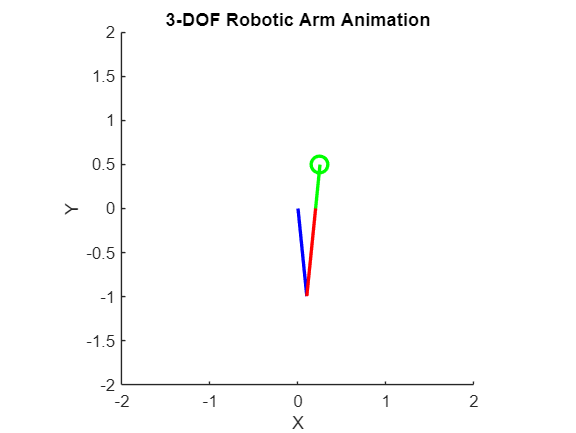

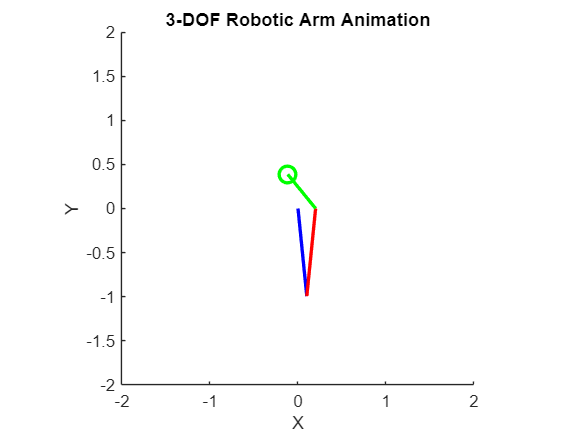

clc; clear; close all;  
L1 = 1;
L2 = 1;
L3 = 0.5;  
t = linspace(0, 10, 100);
radius = 0.2; 
center = [0; 0]; 
theta = linspace(0, 2*pi, length(t)); 
x = center(1) + radius * cos(theta); 
y = center(2) + radius * sin(theta);  
q1 = zeros(1, length(t)); 
q2 = zeros(1, length(t)); 
q3 = linspace(0, pi/4, length(t)); 
for i = 1:length(t) 
    q2(i) = acos((x(i)^2 + y(i)^2 - L1^2 - L2^2) / (2 * L1 * L2)); 
    q1(i) = atan2(y(i), x(i)) - atan2(L2 * sin(q2(i)), L1 + L2 * cos(q2(i))); 
end  
figure; 
hold on; 
axis equal; 
xlim([-2, 2]); 
ylim([-2, 2]); 
xlabel('X'); 
ylabel('Y'); 
title('3-DOF Robotic Arm Animation'); 
for i = 1:length(t) 
    x0 = 0; 
    y0 = 0; 
    x1 = L1 * cos(q1(i)); 
    y1 = L1 * sin(q1(i)); 
    x2 = x1 + L2 * cos(q1(i) + q2(i)); 
    y2 = y1 + L2 * sin(q1(i) + q2(i)); 
    x3 = x2 + L3 * cos(q1(i) + q2(i) + q3(i));  % Position for the 3rd link
    y3 = y2 + L3 * sin(q1(i) + q2(i) + q3(i));  
    cla; 
    plot([x0, x1], [y0, y1], 'b', 'LineWidth', 2); 
    hold on; 
    plot([x1, x2], [y1, y2], 'r', 'LineWidth', 2); 
    plot([x2, x3], [y2, y3], 'g', 'LineWidth', 2);  % 3rd link
    plot(x3, y3, 'go', 'MarkerSize', 10, 'LineWidth', 2);  % End-effector
    drawnow; 
    pause(0.05); 
end  